clear;
clear all;
clc;

Entrega 1 - PMR3523 Controle Moderno

Linearização

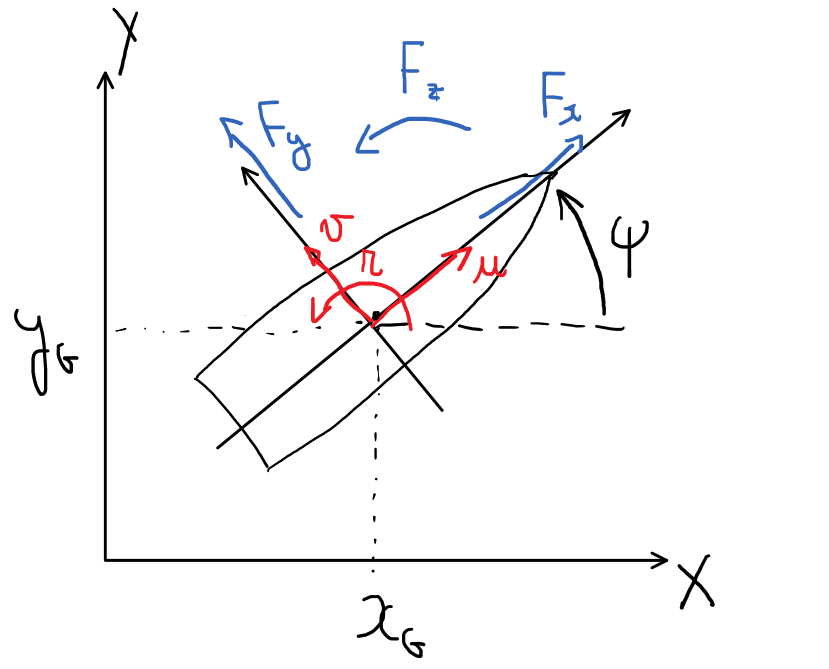

As equações utilizadas são:

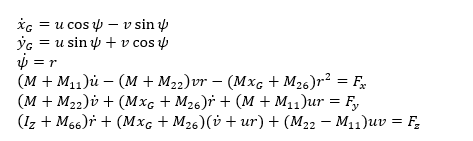      

Sendo as variáveis:

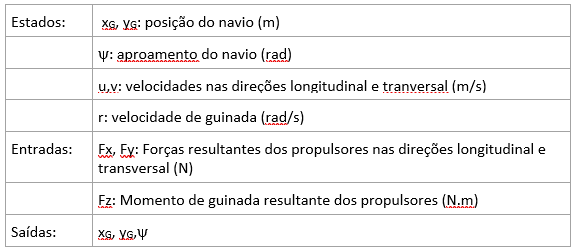

Considerando os parâmetros do navio de suporte à plataforma Maersk Handler:  

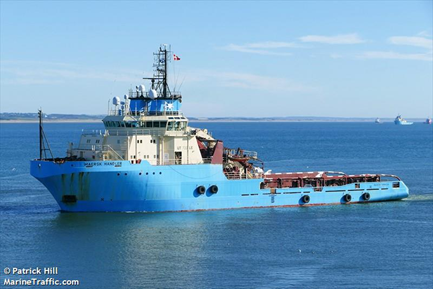        

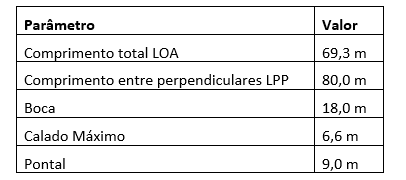

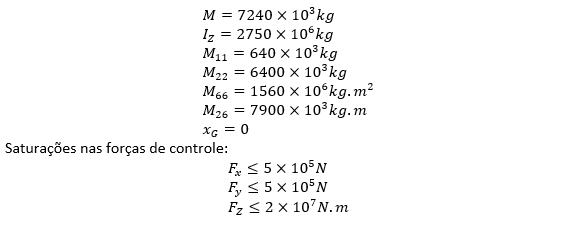

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

E as condições de linearização:

syms xg psi u v r Fx Fy Fz v_dot_lin r_dot_lin

xg_dot = u*cos(psi) - v*sin(psi)

$$xg\_dot = u\,\cos\left(\psi \right)-v\,\sin\left(\psi \right)$$

yg_dot = u*sin(psi) - v*cos(psi)

$$yg\_dot = u\,\sin\left(\psi \right)-v\,\cos\left(\psi \right)$$

psi_dot = r

$$psi\_dot = r$$

u_dot = (Fx + (m*xg + m26)*r^2 + (m + m22)*v*r)/(m+m11)

$$u\_dot = \frac{\mathrm{Fx}}{7880000}+\frac{341\,r\,v}{197}+\frac{r^{2}\,\left(7240000\,\mathrm{xg}+7900000\right)}{7880000}$$

v_dot = (Fy -(m*xg + m26)*r_dot_lin - (m + m11)*u*r)/(m+m22)

$$v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{{\dot{r}}_{\mathrm{lin}}\,\left(7240000\,\mathrm{xg}+7900000\right)}{13640000}-\frac{197\,r\,u}{341}$$

r_dot = (Fz - (m*xg + m26)*(v_dot_lin + u*r) - (m22 - m11)*u*v)/(izz + m66)

$$r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{72\,u\,v}{53875}-\frac{\left({\dot{v}}_{\mathrm{lin}}+r\,u\right)\,\left(7240000\,\mathrm{xg}+7900000\right)}{4310000000}$$

Linearizando as equações:

lin_xg_dot = taylor(xg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_xg\_dot = u$$


lin_yg_dot = taylor(yg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_yg\_dot = -v$$


lin_psi_dot = taylor(psi_dot, r , 0 , 'Order', 2)

$$lin\_psi\_dot = r$$


lin_u_dot = taylor(u_dot, [xg, r, v, Fx], 0 , 'Order', 2)

$$lin\_u\_dot = \frac{\mathrm{Fx}}{7880000}$$


lin_v_dot = taylor(v_dot, [xg, r_dot_lin, u, r, Fy], 0 , 'Order', 2)

$$lin\_v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{395\,{\dot{r}}_{\mathrm{lin}}}{682}$$


lin_r_dot = taylor(r_dot, [xg, v_dot_lin, u, r, v, Fz], 0 , 'Order', 2)

$$lin\_r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{79\,{\dot{v}}_{\mathrm{lin}}}{43100}$$